[Belegarbeit 2](https://nextcloud.th-wildau.de/nextcloud/index.php/s/ZNs6PeAF4domdEN) vorgetragen von Tom Quast & Hannes König

Lösung zu Aufgage 1:

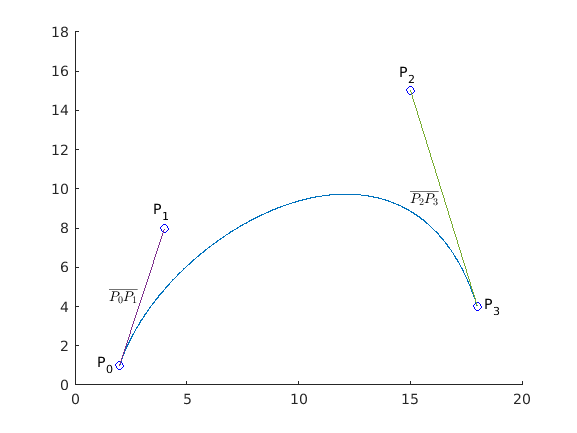

clear
% Parameter t und Kontrollpunkte als  Matrix definieren:
t = 0:.001:1;
P0 = [2,1];
P1 = [4,8];
P2 = [15,15];
P3 = [18,4];
P = [P0;P1;P2;P3];
% definieren der Basisfunktionen (Polynome):
b0 = (1-t).^3;
b1 = 3*(1-t).^2.*t;
b2 = 3*(1-t).*t.^2;
b3 = t.^3;
% kubische Gleichung in Parameterform:
x = P0(1) * b0 + P1(1) * b1 + P2(1) * b2 + P3(1) * b3;
y = P0(2) * b0 + P1(2) * b1 + P2(2) * b2 + P3(2) * b3;
% Beschriftungen einfügen:
text(P0(1) - 1,P0(2),'P_{0}')
text(P1(1) - 0.5,P1(2) + 0.8,'P_{1}')
text(P2(1) - 0.5,P2(2) + 0.8,'P_{2}')
text(P3(1) + 0.3,P3(2),'P_{3}')
txt = '$ \overline{P_{0}P_{1}} $';
text ((P0(1) + P1(1))/2 - 1.5,(P0(2) + P1(2))/2,txt,'interpreter','latex')
txt = '$ \overline{P_{2}P_{3}} $';
text ((P2(1) + P3(1))/2 - 1.5,(P2(2) + P3(2))/2,txt,'interpreter','latex')
% Achsen definieren + Plotten der Strecken, der Kurve, sowie der Beschriftungen:
xlim([0 20]);
ylim([0 18]) ; 
hold on
plot(x,y)
plot(P(:,1),P(:,2),'bo')
plot(P(:,1),P(:,2),'bo')
plot(P(1:2,1),P(1:2,2))
plot(P(3:4,1),P(3:4,2))

Die Strecken $$ \overline{P_{0}P_{1}} $$ & $$ \overline{P_{2}P_{3}} $$ scheinen tangential an die Bézierkurve in den Kontrollpunkten $$$ P_{0}$ & $$$ P_{3}$ zu münden